# Network Model

## Scope and Definition of Network Models

Many operations research situations can be modeled and solved as networks (nodes connected by branches):

- Design of an offshore natural-gas pipeline network connecting wellheads in the Gulf of Mexico to an inshore delivery point with the objective of minimizing the cost of constructing the pipeline.

- Determination of the shortest route between two cities in an existing network of roads.

- Determination of the maximum capacity (in tons per year) of a coal slurry pipeline network joining coal mines in Wyoming with power plants in Houston. (Slurry pipelines transport coal by pumping water through specially designed pipes.)

- Determination of the time schedule (start and completion dates) for the activities of a construction project.

The solution of these situations is accomplished through a variety of network optimization algorithms. This chapter presents four of these algorithms.

- Minimal spanning tree (situation 1)

- Shortest-route algorithm (situation 2)

- Maximal-flow algorithm (situation 3)

- Critical Path Method (CPM) algorithm (situation 4)

## Network definitions

A network consists of a set of nodes linked by arcs (or branches). The notation for describing a network is $(N, A)$, where $N$ is the set of nodes, and $A$ is the set of arcs. 

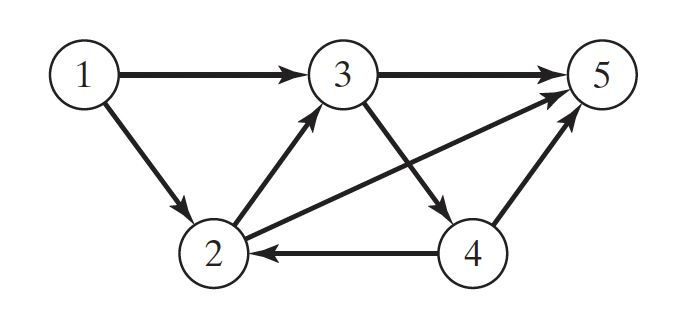

**Figure 1: **Example of (N, A) Network

As an illustration, the network in **Figure 1** is described as


$$N = {1, 2, 3, 4, 5}$$



$$A = \{ (1,2),(1,3),(2,3),(2,5),(3,4),(3,5),(4,2),(4,5) \}$$


Associated with each network is a **flow** (e.g., oil products flow in a pipeline and automobile traffic flow in highways). The maximum flow in a network can be finite or infinite, depending on the capacity of its arcs.

An **arc** is said to be **directed** or **oriented** if it allows positive flow in one direction only. A **directed network** has all directed arcs.

A **path** is a set of arcs joining two distinct nodes, passing through other nodes in the network. For example, in **Figure 1**, arcs (1, 2), (2, 3), (3, 4), and (4, 5) form a path between nodes 1 and 5. A path forms a **cycle** or a **loop** if it connects a node back to itself through other nodes. In **Figure 1**, arcs (2, 3), (3, 4), and (4, 2) form a cycle.

A network is said to be **connected** if every two distinct nodes are linked by at least one path. The network in **Figure 1** demonstrates this type of network. A **tree** is a cycle-free connected network comprised of a subset of all the nodes, and a **spanning tree **links all the nodes of the network. **Figure 2** provides examples of a tree and a spanning tree from the network in **Figure 1**.

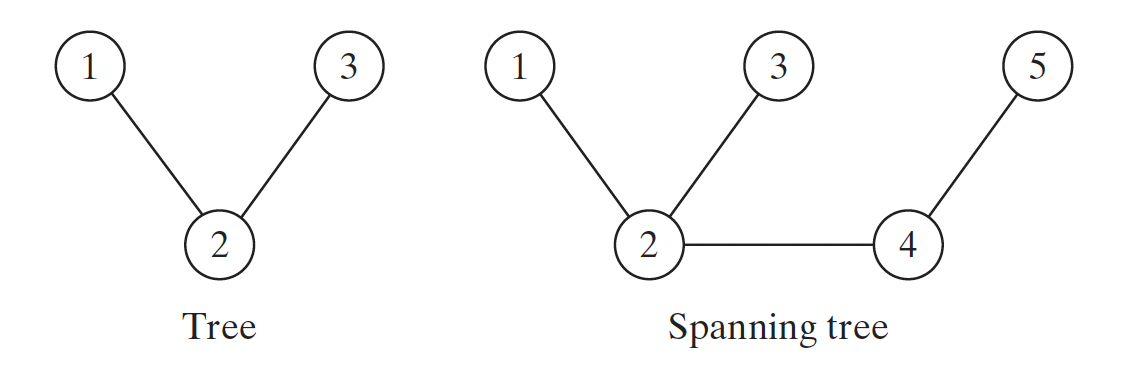

**Figure 2:** Examples of a tree and a spanning tree

# shortestpath

Shortest path between two single nodes

## Syntax

`P = shortestpath(G,s,t)`

`P = shortestpath(G,s,t,'Method',algorithm)`

`[P,d] = shortestpath(``___``)`

`[P,d,edgepath] = shortestpath(``___``)`

## Description

`P ``= shortestpath(G,s,t)` computes the shortest path starting at source node `s` and ending at target node `t`. If the graph is weighted (that is, `G.Edges` contains a variable `Weight`), then those weights are used as the distances along the edges in the graph. Otherwise, all edge distances are taken to be `1`.

`P = shortestpath(G,s,t,'Method',algorithm)` optionally specifies the algorithm to use in computing the shortest path. For example, if `G` is a weighted graph, then `shortestpath(G,s,t,'Method','unweighted')` ignores the edge weights in `G` and instead treats all edge weights as `1`.

`[P,d] = shortestpath(___)` additionally returns the length of the shortest path, `d`, using any of the input arguments in previous syntaxes.

`[P,d,edgepath] = shortestpath(___)` additionally returns the edge indices `edgepath` of all edges on the shortest path from `s` to `t`.

### Example 1: **Shortest Path Between Specified Nodes**

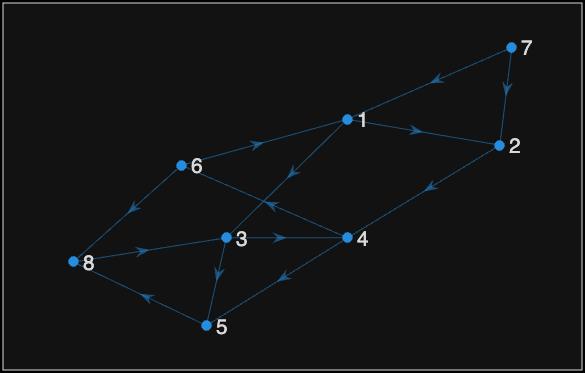

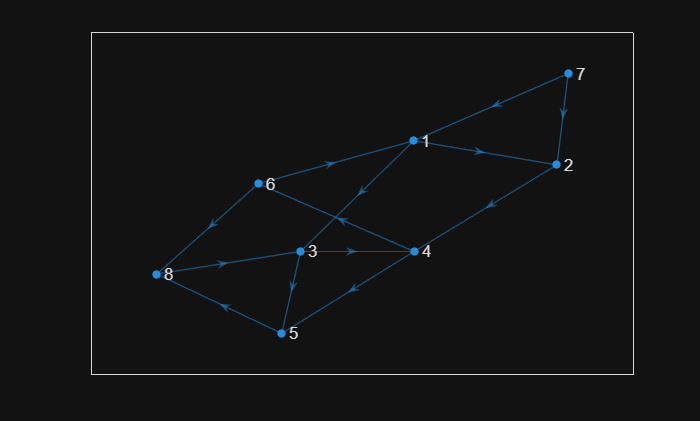

% Create and plot a directed graph
s1 =   [1;   1;   2;   3;   3;   4;   4;   5;   6;   6;   7;   7;   8];
t1 =   [2;   3;   4;   4;   5;   5;   6;   8;   1;   8;   1;   2;   3];
G1 = digraph(s1,t1);
plot(G1)

% Calculate the shortest path between nodes 7 and 8
P1 = shortestpath(G1,7,8)

P1 =      7     1     3     5     8


### Example 2: **Shortest Path in Weighted Graph**

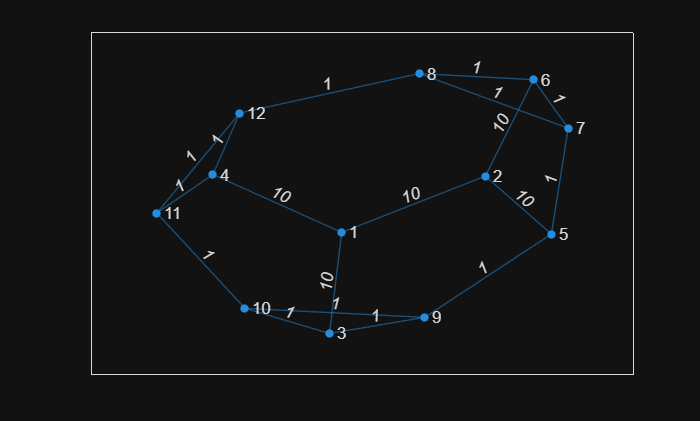

% Create and plot a graph with weighted edges
s2      =   [1;   1;   1;   2;   2;   6;   6;   7;   7;   3;   3;   9;   9;   4;   4;  11;  11;   8];
t2      =   [2;   3;   4;   5;   6;   7;   8;   5;   8;   9;  10;   5;  10;  11;  12;  10;  12;  12];
wght2   =  [10;  10;  10;  10;  10;   1;   1;   1;   1;   1;   1;   1;   1;   1;   1;   1;   1;   1];
G2      = graph(s2,t2,wght2);
plot(G2,'EdgeLabel',G2.Edges.Weight);

% Find the shortest path between nodes 3 and 8, 
% and specify two outputs to also return the length of the path
[P2,d2] = shortestpath(G2,3,8)

P2 =      3     9     5     7     8


d2 = 4

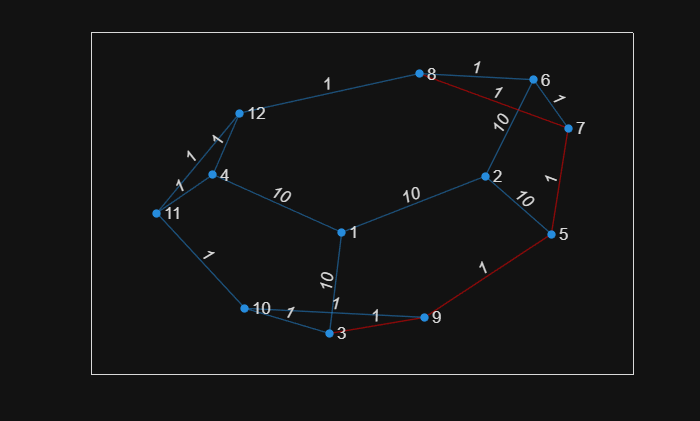

% Highlight the shortest path in green
plot2   = plot(G2,'EdgeLabel',G2.Edges.Weight);
highlight(plot2,P2,'EdgeColor','r')

### Example 3: **Shortest Path in Multigraph**

Find the shortest path between two nodes in a multigraph and highlight the specific edges that are traversed.

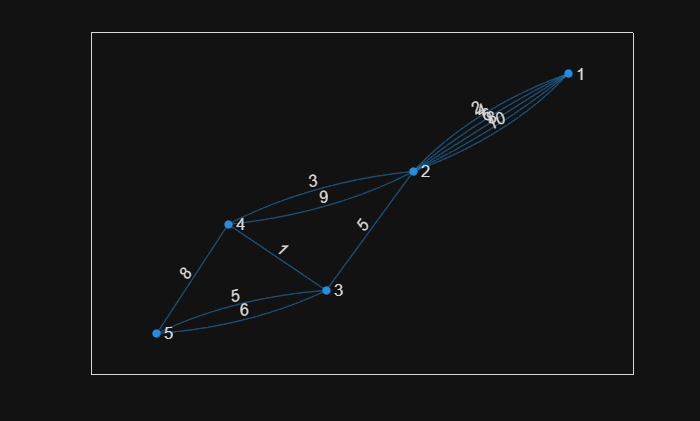

% Create a weighted multigraph with five nodes. 
% Several pairs of nodes have more than one edge between them. 
G3 = graph([1;   1;   1;   1;   1;   2;   2;   2;   3;   3;   3;   4], ...
           [2;   2;   2;   2;   2;   3;   4;   4;   4;   5;   5;   5], ...
           [2;   4;   6;   8;  10;   5;   3;   9;   1;   5;   6;   8]);
plot(G3,'EdgeLabel',G3.Edges.Weight);

% Find the shortest path between nodes 

% 1 and 5
[P3,d3,edgepath3] = shortestpath(G3,1,5)

P3 =      1     2     4     3     5


d3 = 11

edgepath3 =      1     7     9    10


G3.Edges(edgepath3,:);

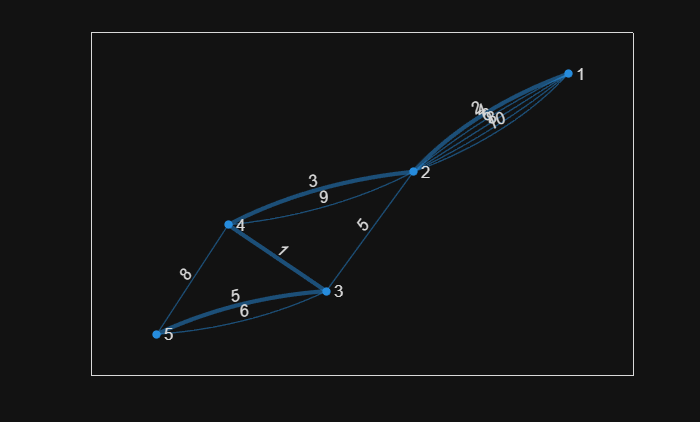


% The shortest path has a total length of 11 and follows the edges given by
G3.Edges(edgepath3,:);
% Highlight this edge path by using the highlight function 
% with the 'Edges' name-value pair to specify the indices of the edges traversed
plot3 = plot(G3,'EdgeLabel',G3.Edges.Weight);
highlight(plot3,'Edges',edgepath3)

### Example 4: **Shortest Path from Node Coordinates**

Find the shortest path between nodes in a graph using the distance between the nodes as the edge weights.

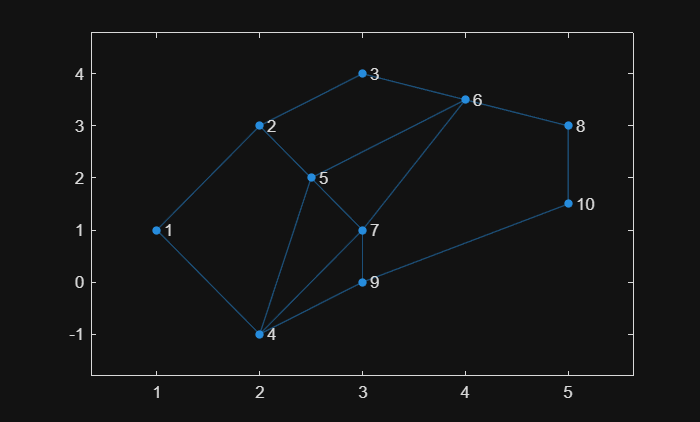

% Create a graph with 10 nodes
s4 = [1;  1;   2;   2;   3;   4;   4;   4;   5;   5;   6;   6;   7;   8;   9];
t4 = [2;  4;   3;   5;   6;   5;   7;   9;   6;   7;   7;   8;   9;  10;  10];
G4 = graph(s4,t4);

% Create x- and y-coordinates for the graph nodes. 
% Then plot the graph using the node coordinates by specifying the 'XData' and 'YData' name-value pairs.
xCoor4 = [1;   2;   3;   2; 2.5;   4;   3;   5;   3;   5];
yCoor4 = [1;   3;   4;  -1;   2; 3.5;   1;   3;   0; 1.5];
plot(G4,'XData',xCoor4,'YData',yCoor4)

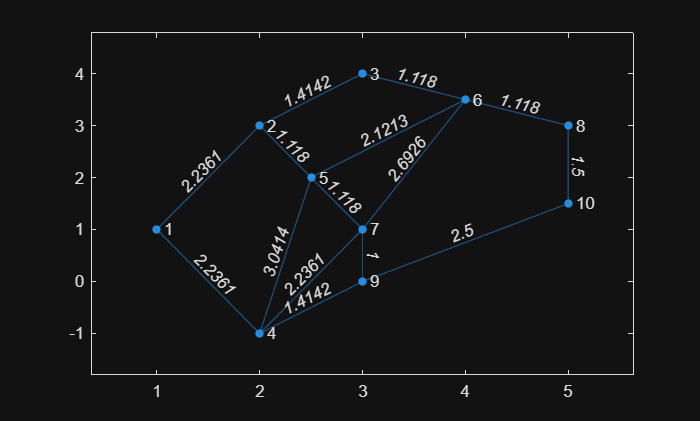

% Add edge weights to the graph by computing the Euclidean distances between the graph nodes. 

% Use "findedges" function to obtain vectors sn and tn describing the source and target nodes of each edge in the graph. 
[sn,tn] = findedge(G4);

dx = xCoor4(sn) - xCoor4(tn);
dy = yCoor4(sn) - yCoor4(tn);

% Use "hypot" function to compute the square root of the sum of squares, 
% so specify Δx and Δy as the input arguments to calculate the length of each edge.
length = hypot(dx, dy);
G4.Edges.Weight = length;

plot(G4,'XData',xCoor4,'YData',yCoor4,'EdgeLabel',G4.Edges.Weight);

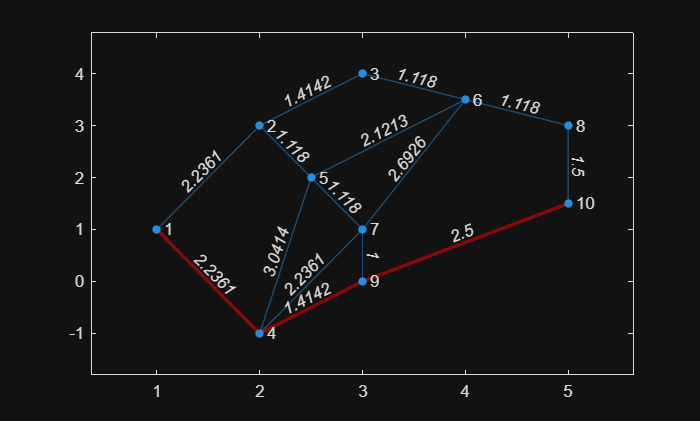

% Find the shortest path between node 1 and node 10 and 
% specify two outputs to also return the path length. 

[P4,d4] = shortestpath(G4,1,10);

% Use the highlight function to display the path in the plot.
plot4 = plot(G4,'XData',xCoor4,'YData',yCoor4,'EdgeLabel',G4.Edges.Weight);

highlight(plot4,P4,'EdgeColor','r','LineWidth',2)

# shortestpathtree

Shortest path tree from node

## Syntax

`TR = shortestpathtree(G,s)`

`TR = shortestpathtree(G,s,t)`

`TR = shortestpathtree(___,Name,Value)`

`[TR,D] = shortestpathtree(___)`

`[TR,D,E] = shortestpathtree(___)`

## Description

`TR = shortestpathtree(G,s)` returns a directed graph, `TR`, that contains the tree of shortest paths from source node `s` to all other nodes in the graph. If the graph is weighted (that is, `G.Edges` contains a variable `Weight`), then those weights are used as the distances along the edges in the graph. Otherwise, all edge distances are taken to be `1`.

`TR = shortestpathtree(G,s,t)` computes the tree of shortest paths between multiple source or target nodes:

- `s` can be a single source node, and `t` can specify multiple target nodes.

- `s` can specify several source nodes, and `t` can specify a single target node.

`TR = shortestpathtree(___,Name,Value)` uses additional options specified by one or more Name-Value pair arguments, using any of the input argument combinations in previous syntaxes. For example, `shortestpathtree(G,s,'OutputForm','vector')` returns a numeric vector that describes the shortest path tree.

`[TR,D] = shortestpathtree(___)` additionally returns the shortest path distance between nodes in the tree.

`[TR,D,E] = shortestpathtree(___)` additionally returns a logical vector `E` that indicates whether each graph edge is in `TR`.

### Example 5: **Shortest Path Between Specified Nodes**

Find the shortest paths from a source node to each of the other reachable nodes in a graph, and plot the results.

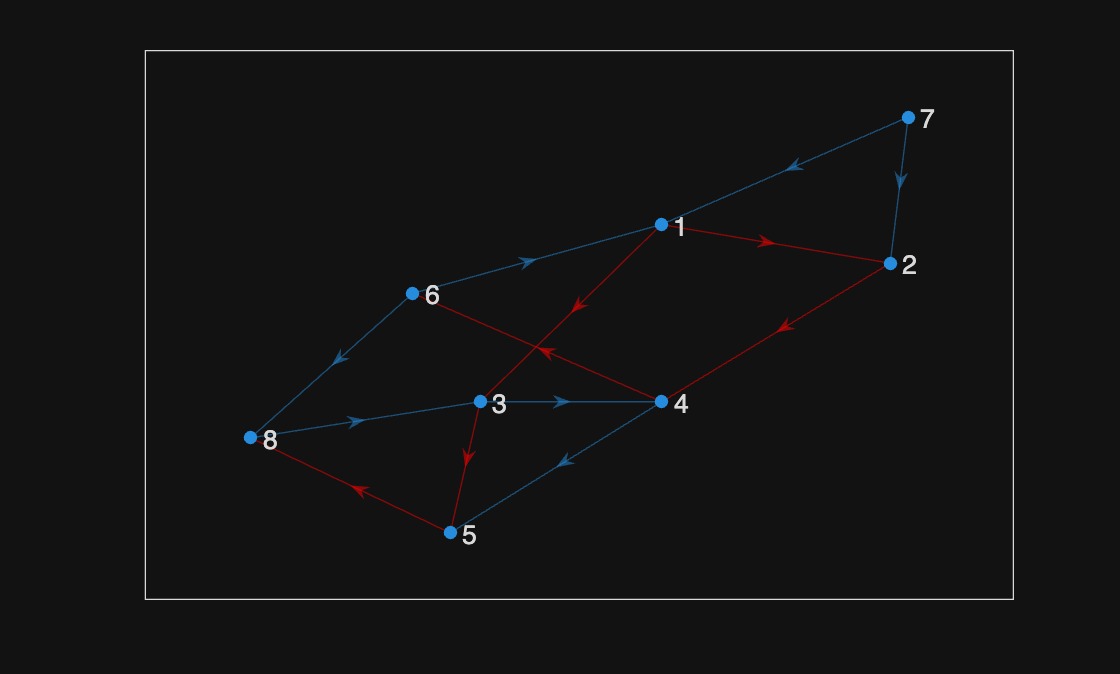

% Using G1, calculate the shortest paths from node 1 to each of the other reachable nodes in the graph. 
% Then, plot the resulting tree on top of the graph.
TR5     = shortestpathtree(G1,1);
plot5   = plot(G1);
% Since there is no path from node 1 to node 7, node 7 is disconnected from the tree.
highlight(plot5,TR5,'EdgeColor','r')

### Example 6: **Shortest Paths to Specified Target Node**

Find the shortest paths from each node in a graph to a target node, and plot the results.

% Create and plot a graph
s6 =   [1;   1;   1;   1;   1;   1;   1;   2;   2;   7;   7;   7;   7;   9;   9;   3;   3;   1;   6;   4;   8;  10;   6;   8;   4;   5];
t6 =   [2;   3;   4;   5;   6;   8;   7;   6;   7;   5;   6;   8;   9;   6;   8;   6;  10;  10;  10;  10;  10;  11;  11;  11;   8;   8];
G6 = graph(s6,t6);

xCorr6 = [0; 0.5; -0.5; -0.5;  0.5; 0; 1.5;  0; 2; -1.5; -2];
yCorr6 = [0; 0.5;  0.5; -0.5; -0.5; 2;   0; -2; 0;    0; 0];
plot(G6,'XData',xCorr6,'YData',yCorr6)
% Find the shortest paths from each node in the graph to node 10. Plot the resulting tree.
[TR6,D6] = shortestpathtree(G6,'all',10);
D6
plot(TR6)

# distances

Shortest path distances of all node pairs

## Syntax

`d = distances(G)`

`d = distances(G,s)`

`d = distances(G,s,t)`

`d = distances(___,'Method',algorithm)`

## Description

`d = distances(G)` returns a matrix, `d`, where `d(i,j)` is the length of the shortest path between node `i` and node `j`. If the graph is weighted (that is, `G.Edges` contains a variable `Weight`), then those weights are used as the distances along the edges in the graph. Otherwise, all edge distances are taken to be `1`.

`d = distances(G,s)` restricts the source nodes to the nodes defined by `s`, such that `d(i,j)` is the distance from node `s(i)` to node `j`.

`d = distances(G,s,t)` additionally restricts the target nodes to the nodes defined by `t`, such that `d(i,j)` is the distance from node `s(i)` to node `t(j)`.

`d = distances(___,'Method',algorithm)` optionally specifies the algorithm to use in computing the shortest path using any of the input arguments in previous syntaxes. For example, if `G` is a weighted graph, then `distances(G,'Method','unweighted')` ignores the edge weights in `G` and instead treats all edge weights as `1`.

### Example 7: **Shortest Path Distances for All Node Pairs and from/to Specified Sources**

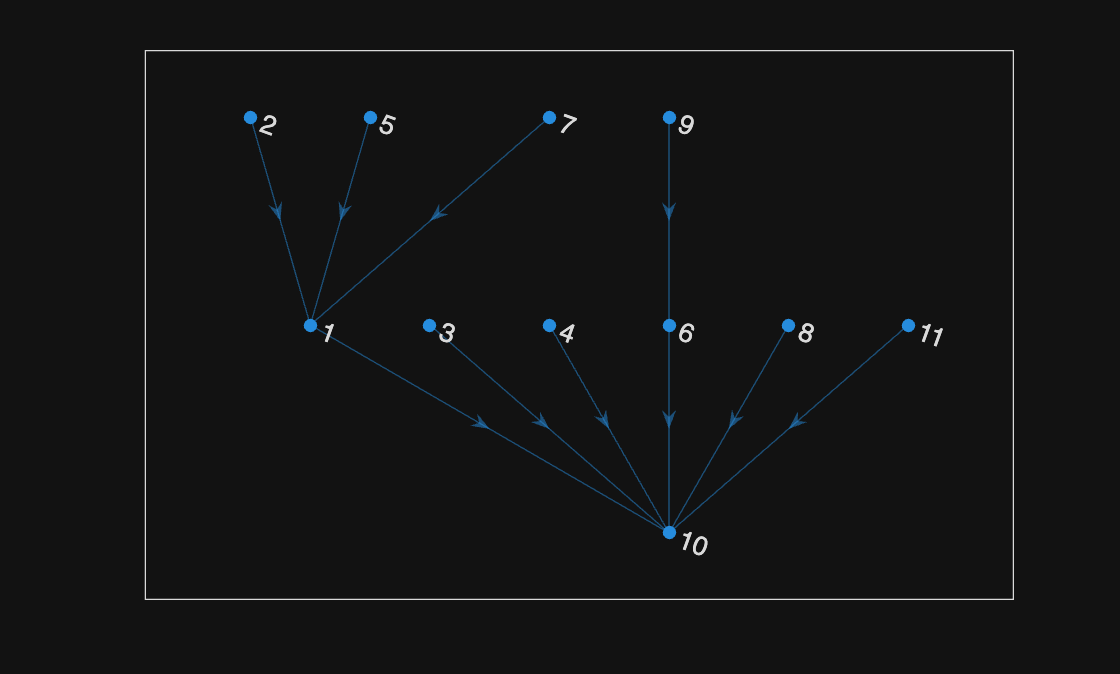

% Create and plot a graph
s7 =   [1;   1;   1;   2;   2;   3;   3;   4;   5;   5;   6;   7;   8;   8;  10;  11];

t7 =   [2;   3;  10;   4;  12;   5;   4;   6;   6;   7;   9;   8;   9;  11;  11;  12];
G7 = graph(s7,t7);
plot(G7)
% Calculate the shortest path distance between all node pairs in the graph.
d7 = distances(G7)

% d is symmetric because G is an undirected graph. 
% In general d(i,j) is the length of the shortest path between node i and node j, 
% and for undirected graphs this is equivalent to d(j,i).

% Find the shortest path distances from nodes 5 and 7 to nodes 2 and 3.
sources = [5; 7];
targets = [2; 3];
d7_sub = distances(G7,sources,targets)

### Example 8: **Shortest Path Distances for the **graph with weighted edges

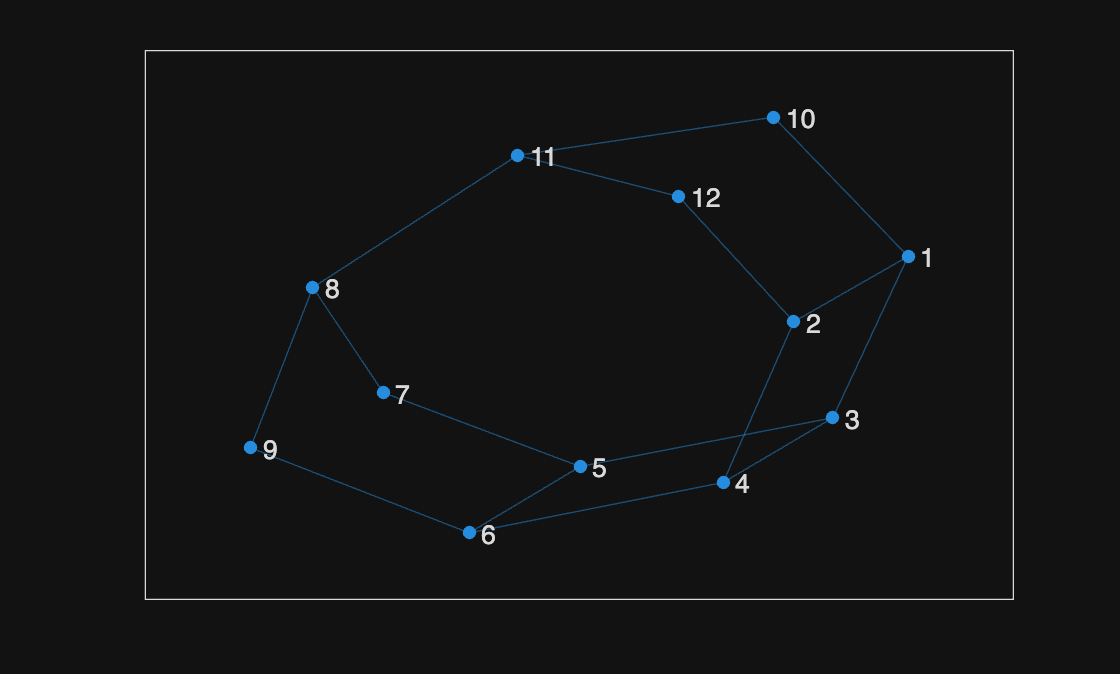

% Create and plot a directed graph with weighted edges
s8 =      [1;   1;   1;   2;   5;   3;   6;   4;   7;   8;   8;   8];
t8 =      [2;   3;   4;   5;   3;   6;   4;   7;   2;   6;   7;   5];
wght8 = [100;  10;  10;  10;  10;  20;  10;  30;  50;  10;  70;  10];
G8 = digraph(s8,t8,wght8);

plot(G8,'EdgeLabel',G8.Edges.Weight)
% Find the shortest path distance between all pairs of graph nodes

d7 =      0     1     1     2     2     3     3     3     4     1     2     2
     1     0     2     1     3     2     4     3     3     2     2     1
     1     2     0     1     1     2     2     3     3     2     3     3
     2     1     1     0     2     1     3     3     2     3     3     2
     2     3     1     2     0     1     1     2     2     3     3     4
     3     2     2     1     1     0     2     2     1     4     3     3
     3     4     2     3     1     2     0     1     2     3     2     3
     3     3     3     3     2     2     1     0     1     2     1     2
     4     3     3     2     2     1     2     1     0     3     2     3
     1     2     2     3     3     4     3     2     3     0     1     2
     2     2     3     3     3     3     2     1     2     1     0     1
     2     1     3     2     4     3     3     2     3     2     1     0


d8 = distances(G8)

% Since G is a directed graph, d is not symmetric, and d(i,j) corresponds to the distance between nodes i and j. 
% The Inf values in d correspond to nodes that are unreachable. 
% For example, since node 1 has no predecessors, it is not possible to reach node 1 from any other node in the graph. 
% So the first column of d contains many Inf values to reflect that node 1 is unreachable.

% Specify 'Method' as 'unweighted' to ignore the edge weights and treat all edge distances as 1.
d8_unwght = distances(G8,'Method','unweighted')

d7_sub =      3     1
     4     2


# maxflow

Maximum flow in graph

## Syntax

`mf = maxflow(G,s,t)`

`mf = maxflow(G,s,t,algorithm)`

`[mf,GF] = maxflow(___)`

`[mf,GF,cs,ct] = maxflow(___)`

## Description

`mf = maxflow(G,s,t)` returns the maximum flow between nodes `s` and `t`. If graph `G` is unweighted (that is, `G.Edges` does not contain the variable `Weight`), then `maxflow` treats all graph edges as having a weight equal to 1.

`mf = maxflow(G,s,t,algorithm)` specifies the maximum flow algorithm to use. This syntax is only available if `G` is a directed graph.

`[mf,GF] = maxflow(___)` also returns a directed graph object, `GF`, using any of the input arguments in previous syntaxes. `GF` is formed using only the edges in `G` that have nonzero flow values.

## Example 9: **Maximum Flow in Graph**

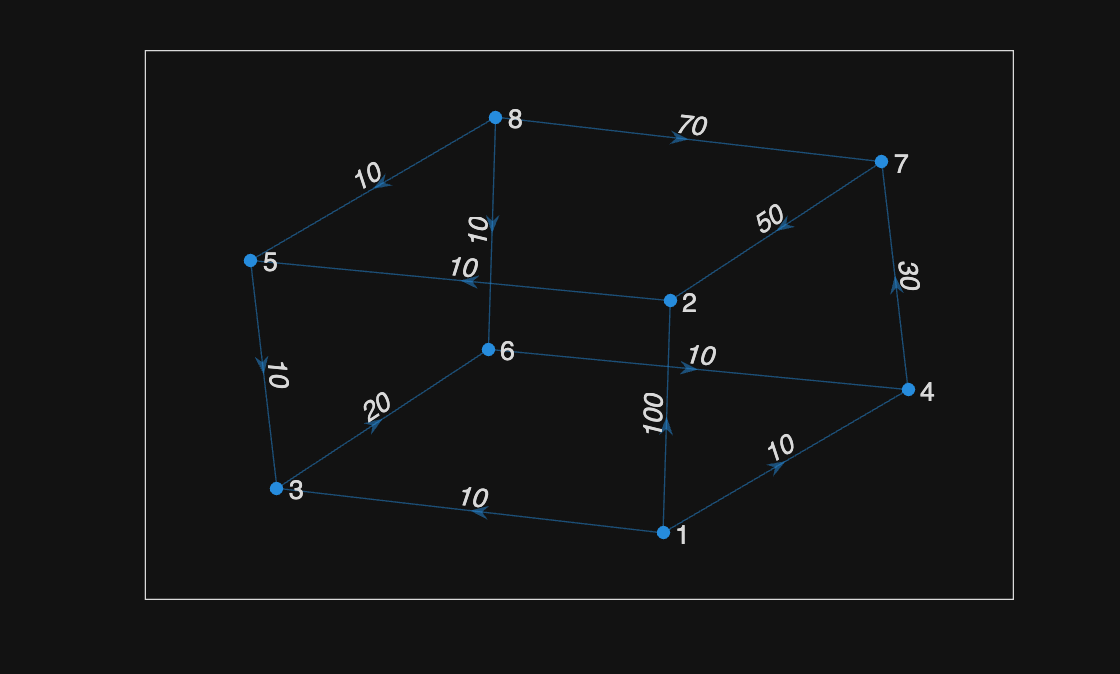

% Create and plot a weighted graph
% The weighted edges represent flow capacities
s9 =        [1;   1;   2;   2;   3;   4;   4;   4;   5;   5];
t9 =        [2;   3;   3;   4;   5;   3;   5;   6;   4;   6];
wght9 =    [77;  44;  67;  75;  89;  90; 200;  76; 100; 100];

G9 = digraph(s9,t9,wght9);

plot(G9,'EdgeLabel',G9.Edges.Weight,'Layout','layered');
% Determine the maximum flow from node 1 to node 6 in the weighted graph G9

d8 =      0    90    10    10   100    30    40   Inf
   Inf     0    20    50    10    40    80   Inf
   Inf   110     0    30   120    20    60   Inf
   Inf    80   100     0    90   120    30   Inf
   Inf   120    10    40     0    30    70   Inf
   Inf    90   110    10   100     0    40   Inf
   Inf    50    70   100    60    90     0   Inf
   Inf   100    20    20    10    10    50     0


[mf9,GF9] = maxflow(G9,1,6);
% Display the results of the optimization
disp('The maximum flow from node 1 to node 6:');
disp(mf9);
% Report the graph of nonzero flows
[GF9.Edges.EndNodes, GF9.Edges.Weight]

## Example 10: **Maximum Flow with H**ighlight and Label of Nonzero Flows

% Create and plot a graph
s10     =  [1;   1;   2;   2;   3;   3;   4];

d8_unwght =      0     1     1     1     2     2     2   Inf
   Inf     0     2     4     1     3     5   Inf
   Inf     4     0     2     5     1     3   Inf
   Inf     2     4     0     3     5     1   Inf
   Inf     5     1     3     0     2     4   Inf
   Inf     3     5     1     4     0     2   Inf
   Inf     1     3     5     2     4     0   Inf
   Inf     2     2     2     1     1     1     0


t10     =  [2;   3;   3;   4;   4;   5;   5];
wght10  = [10;   6;  15;   5;  10;   3;   8];

G10 = digraph(s10,t10,wght10);
plot(G10,'EdgeLabel',G10.Edges.Weight);
% Find the maximum flow value between node 1 and node 5. 

[mf10,GF10] = maxflow(G10,1,5);

disp('The maximum flow from node 1 to node 5:');
disp(mf10);

% Highlight and label the graph of nonzero flows
plot10 = plot(G10,'EdgeLabel',G10.Edges.Weight);
plot10.EdgeLabel = {};

highlight(plot10,GF10,'EdgeColor','r','LineWidth',2);

st = GF10.Edges.EndNodes;
labeledge(plot10,st(:,1),st(:,2),GF10.Edges.Weight);

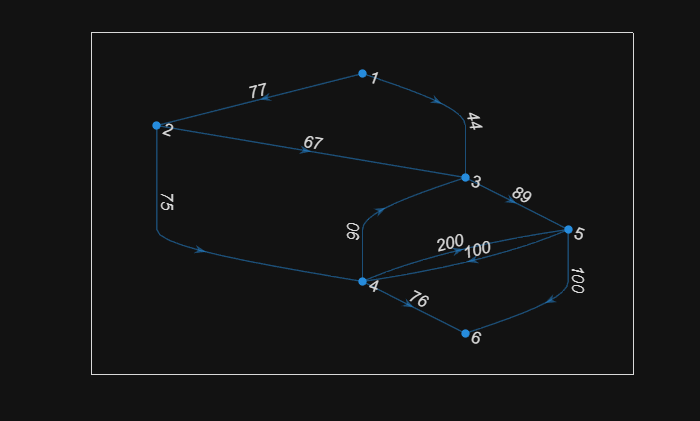

The maximum flow from node 1 to node 6:


   121



ans =      1     2    77
     1     3    44
     2     3     2
     2     4    75
     3     5    46
     4     6    75
     5     6    46


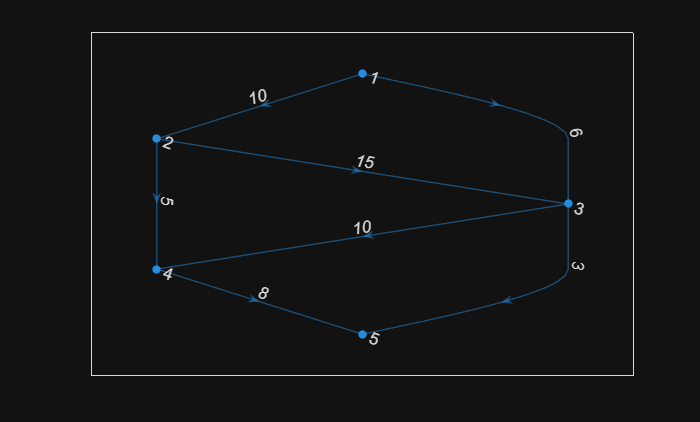

The maximum flow from node 1 to node 5:


    11



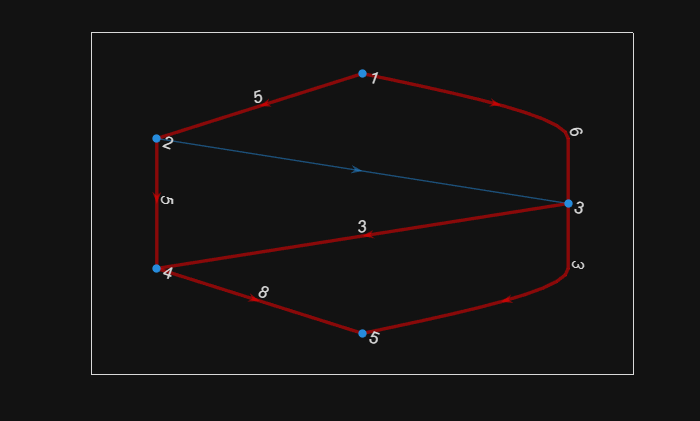

Unrecognized function or variable 'st'.

`End-of-file`

`Pongsun B.`

`2025-10-16`